**Aufgabe**: 

a.) Führen Sie eine LPC-Analyse für einen Vokal und einen Konsonanten durch. Schneiden Sie hierzu aus einem Sprachsignal eine ca. 20ms lange Sequenz aus, die den jeweiligen Laut enthält. Bestimmen Sie den inversen und den Synthesefilter. Zeichnen Sie für beide Laute die Zero-Pole-Darstellung und interpretieren Sie das Ergebnis. Berechnen Sie anschliessend den Frequenzgang des Synthesefilters und  vergleichen Sie das Ergebnis mit dem Leitungsspektrum ihres Signals. 

**Frage**: Variieren Sie die Prädikatorordnung M und beschreiben das beobachtete Verhalten.

**Lösung**: Mit steigender Prädikatorordnung also Anzahl an Punkten, die zur Vorhersage des Signals verwendet werden, wächst die Auflösung und Genauigkeit des Frequenzganges H(f). Der Fehler nimmt dabei sukessive ab:

**Konsonaten** als rauschartige Signale lassen sich schlechter vorhersagen da deren AKF ein** delta-funktionsartiges** Verhalten zeigt, hingegen quasiperiodische Laute, mit hoher Selbstähnlichkeit, sehr gut vorhergesagt werden können

clear;
close all hidden

**Konstanten**

- Definition der konstanten Größen

%Audiodateien
 
audioFilename_a='wave/Vocal_a.wav'

audioFilename_a = 'wave/Vocal_a.wav'

audioFilename2_f='wave/Consonant_f.wav'

audioFilename2_f = 'wave/Consonant_f.wav'

LM =1;              %Prädiktor Länge in in ms
 
nDFT=512;   %

**Initialisierung**

- Audiodateien einlesen

- Anzahl der Abtastpunkt bestimmen

- Zeitfenster definieren

- Signale plotten

[y_a,fs_a] = audioread(audioFilename_a);
[y_f,fs_f] = audioread(audioFilename2_f);
 
 
N_a = length(y_a);
N_f = length(y_f);
 
dt_a=1/fs_a;
dt_f=1/fs_f;
 
%Berechne M aus Länge des Prädiktorsignals 
 
M_a=LM*fs_a*1e-3;
M_f=LM*fs_f*1e-3;
 
y_a=mean(y_a,2);  %Mittelwert der beiden Spuren in der Audio-Datei
y_f=mean(y_f,2);  %Mittelwert der beiden Spuren in der Audio-Datei~
 
%Abtastzeitpunkte im Zeitraum
t_a = (0:dt_a:N_a*dt_a-dt_a);
t_f = (0:dt_f:N_f*dt_f-dt_f);
 
%Schallsignale plotten
 
subplot(2,1,1);
plot(t_a,y_a);
xlabel('Zeit in (s)');
ylabel('y(t)');
%xlim([0 3]);
title('Laut [a] ');
hold on
 
subplot(2,1,2);
plot(t_f,y_f);
xlabel('Zeit in (s)');
ylabel('y(t)');
title('Laut [f]');
hold on;

**Segment mit Fensterfunktion am Rand glätten**

- Fensterfunktion Hamming-Fenster

- Sprachsignale am Rand glätten: y(n_0-M),…, y(n_0- 1) = 0

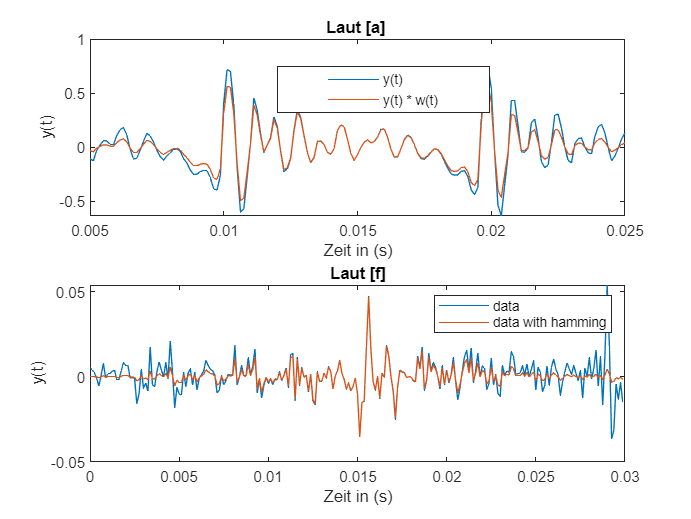

win_a = hamming(length(y_a));   % Fensterfunktion
win_s = hamming(length(y_f));   % Fensterfunktion
y_a = y_a.*win_a;
y_f = y_f.*win_s;
 
figure(1)
subplot(2,1,1);
plot(t_a,y_a);
legend('y(t)', 'y(t) * w(t)')
xlim([0.005 0.025])
hold off
 
subplot(2,1,2);
plot(t_f,y_f);
legend('data', 'data with hamming')
hold off
 
subplot(2,1,1)
legend("Position",[0.40314,0.7819,0.30363,0.090344])

**LPC-Analyse der Signale (Ordnung M)**

- Bestimmung der Prädiktor Koeffizienten a für die Ordnung M

- Funktion:  lpc

-     Input: Signal y(t)

-     Input: Prädiktorordnung M

-     Output: Koeffizienten a

-     Output: Varianz sig

%------------------------------------------------------------------------
 
disp(['Prädiktorordnung für stimmhaften Laut: ',num2str(M_a),' '] )

Prädiktorordnung für stimmhaften Laut: 8 


disp(['Prädiktorordnung für stimmlosen Laut: ' ,num2str(M_f),' '] )

Prädiktorordnung für stimmlosen Laut: 8 


[a_a,sig_a] = lpc(y_a,M_a);  
[a_f,sig_f] = lpc(y_f,M_f);
 
%Energieinhalt des Signals
% 0.54: Korrektur wegen Hamming-Fenster
 
 G_a =  sqrt(sig_a)/0.54;
 G_f =  sqrt(sig_f)/0.54; 
 
disp(['Mittlere Energie des stimmhaften Lautes "a" : ',num2str(G_a),' '] )

Mittlere Energie des stimmhaften Lautes "a" : 0.089883 


disp(['Mittlere Energie des stimmhaften Lautes "f" : ',num2str(G_f),' '] )

Mittlere Energie des stimmhaften Lautes "f" : 0.010643 


**Berechnung des Leistungsspektrum der Signale**

- function fPowerSPectrum: Berechnet das Leistungsspektrum $\mathrm{P}=10\cdot \log_{10} \left({\left|\mathrm{Y}\right|}^2 \right)$

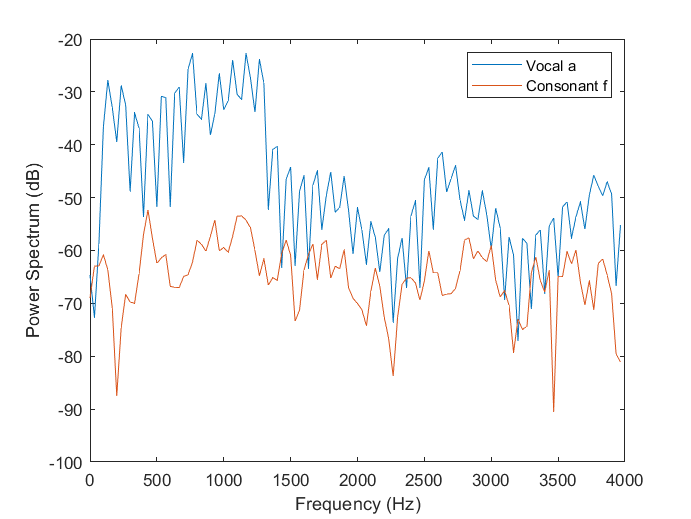

[P_a,f_a]=fPowerSpectrum(y_a,fs_a,N_a);
[P_f,f_f]=fPowerSpectrum(y_f,fs_f,N_f);
 
figure(2)
 
%Plotten der beiden Soektren
plot(f_a,P_a);
hold on ;
 
plot(f_f,P_f);
xlabel('Frequency (Hz)');
ylabel('Power Spectrum (dB)');
legend('Vocal a', 'Consonant f');
hold off;

## Laut "a"

Frequenzgang H(f) und A(f) des 

- Berechnen des Frequenzgang von A(f) und H(f) 

- function: freqz

-     Ouput: Frequenzgang H(f) 

-     Output: Frequenzen f

- Plotten der beiden Frequenzgänge

- Multiplikation der Betragsspektrums des Freqeunzgangs mit der Leistungs des Fehlersignal sigma

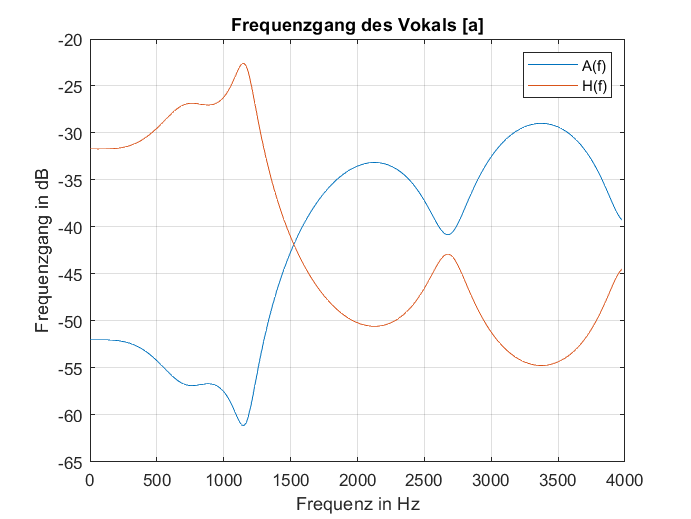

b = 1;
a=a_a;
 
%Frequenzgang A
[A_f,f] = freqz(a,b,N_a,fs_a);
 
figure(3);
plot(f,20*log10(G_a^2*abs(A_f)));   % Betragsspektrum in dB
hold on
xlim([0 4000]);
xlabel('Frequenz in Hz');
ylabel('Frequenzgang in dB');
title('Frequenzgang des Vokals [a]');
 
 
%Frequenzgang H
[H_f,f] = freqz(b,a,N_a,fs_a);
 
plot(f,20*log10(G_a^2*abs(H_f)));   % Betragsspektrum in dB
grid;
legend('A(f)', 'H(f)');

**Pole-Zero-Plots von H(z) und A(z) **

- Berechnen der Nullstellen

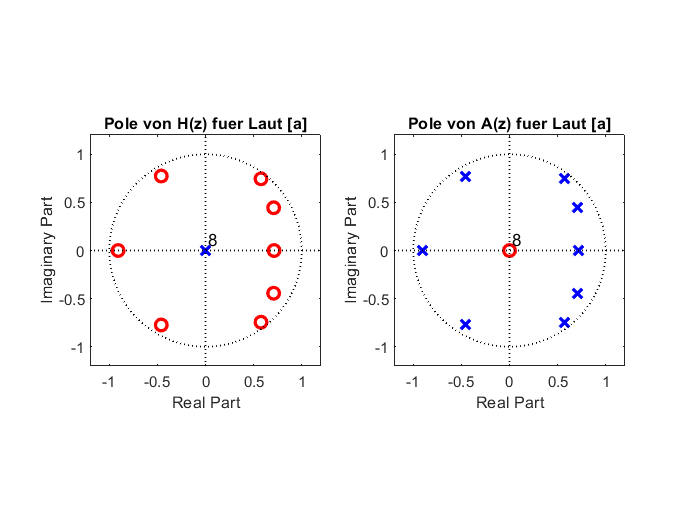

%  Pole und Nullstellen fuer beide Laute darstellen
%--------------------------------------------------------------------------
 
figure(31)
 
subplot(1,2,1) 
[z,p,l]=zplane(a, b);
 
title('Pole von H(z) fuer Laut [a]');
set(l,'LineWidth',1);
set(l,'Color','k');
set(z, 'Color','r');
set(z,'LineWidth',2);
set(p, 'Color','b');
set(p,'LineWidth',2);
xlim([-1.2 1.2])
ylim([-1.2 1.2])
 
subplot(1,2,2) 
 
[z,p,l]=zplane(b, a);
 
title('Pole von A(z) fuer Laut [a]');
set(l,'LineWidth',1);
set(l,'Color','k');
set(z, 'Color','r');
set(z,'LineWidth',2);
set(p, 'Color','b');
set(p,'LineWidth',2);
xlim([-1.2 1.2])
ylim([-1.2 1.2])

**Leistungsspektrum des Signals versus Freqeunzgang H(f)**

- Plotten des Leistungsspektrum P(f) versus H(f)

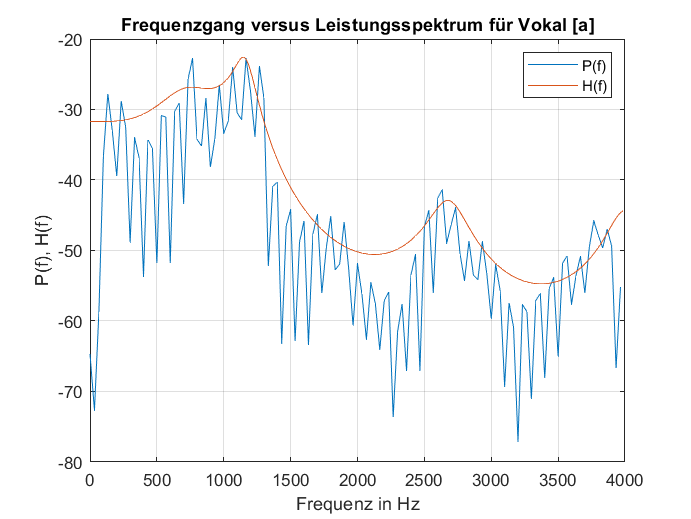

figure(33);
 
plot(f_a,P_a);   % Leistungs
hold on
plot(f,20*log10(G_a^2*abs(H_f)));   % Betragsspektrum in dB
grid;
xlabel('Frequenz in Hz');
ylabel('P(f), H(f)');
title('Frequenzgang versus Leistungsspektrum für Vokal [a]');
xlim([0 4000])
hold off
legend('P(f)','H(f)');

## Laut "f"

Frequenzgang H(f) und A(f) des 

- Berechnen des Frequenzgang von A(f) und H(f) 

- function: freqz

-     Ouput: Frequenzgang H(f) 

-     Output: Frequenzen f

- Plotten der beiden Frequenzgänge

- Multiplikation der Betragsspektrums des Freqeunzgangs mit der Leistungs des Fehlersignal sigma

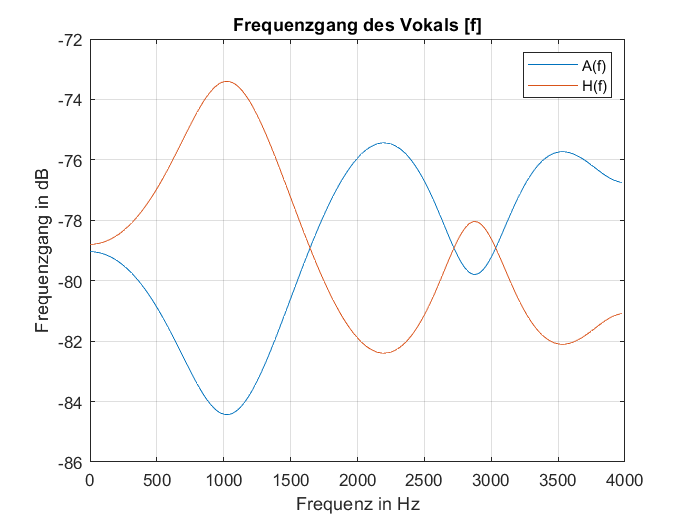

b = 1;
a=a_f;
 
%Frequenzgang A
[A_f,f] = freqz(a,b,N_f,fs_f);
 
figure(41);
plot(f,20*log10(G_f^2*abs(A_f)));   % Betragsspektrum in dB
hold on
xlim([0 4000]);
xlabel('Frequenz in Hz');
ylabel('Frequenzgang in dB');
title('Frequenzgang des Vokals [f]');
 
 
%Frequenzgang H
[H_f,f] = freqz(b,a,N_f,fs_f);
 
plot(f,20*log10(G_f^2*abs(H_f)));   % Betragsspektrum in dB
grid;
legend('A(f)', 'H(f)');

**Pole-Zero-Plots von H(z) und A(z) **

- Berechnen der Nullstellen

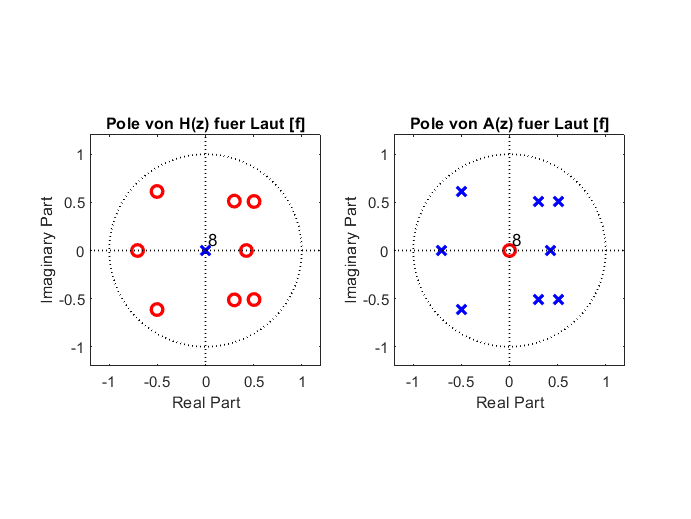

%  Pole und Nullstellen fuer beide Laute darstellen
%--------------------------------------------------------------------------
 
figure(42)
 
subplot(1,2,1) 
[z,p,l]=zplane(a, b);
 
title('Pole von H(z) fuer Laut [f]');
set(l,'LineWidth',1);
set(l,'Color','k');
set(z, 'Color','r');
set(z,'LineWidth',2);
set(p, 'Color','b');
set(p,'LineWidth',2);
xlim([-1.2 1.2])
ylim([-1.2 1.2])
 
subplot(1,2,2) 
 
[z,p,l]=zplane(b, a);
 
title('Pole von A(z) fuer Laut [f]');
set(l,'LineWidth',1);
set(l,'Color','k');
set(z, 'Color','r');
set(z,'LineWidth',2);
set(p, 'Color','b');
set(p,'LineWidth',2);
xlim([-1.2 1.2])
ylim([-1.2 1.2])

**Leistungsspektrum des Signals versus Frequenzgang H(f)**

- Plotten des Leistungsspektrum P(f) versus H(f)

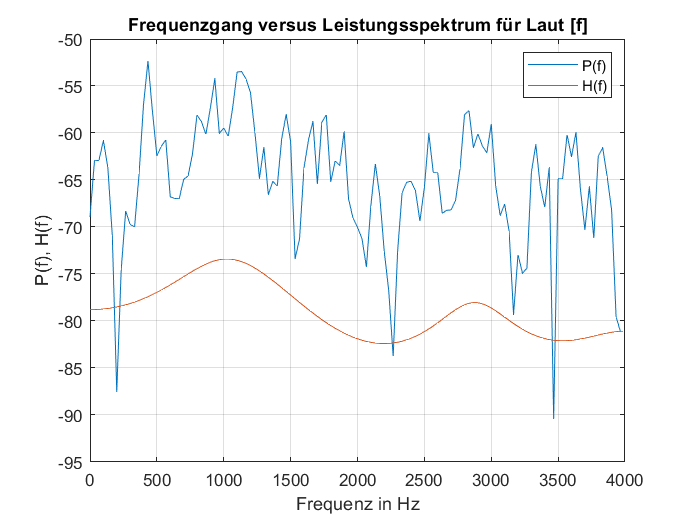

figure(43);
 
plot(f_f,P_f);                      % Leistungsspektrum
hold on
plot(f,20*log10(G_f^2*abs(H_f)));     % Leistungsspektrum in dB
grid;
xlabel('Frequenz in Hz');
ylabel('P(f), H(f)');
title('Frequenzgang versus Leistungsspektrum für Laut [f]');
xlim([0 4000])
hold off
legend('P(f)','H(f)');